# Question #1

**>> Solution**

To solve this problem we will use the function **GAprop_powerThrust_cal.mlx** and **ExecJet_thrustPower_cal.mlx** to calculate corresponding thrust and power value for a given velocity for 2 example aircrafts.

**>> Code**

## Preparations

% For GA propeller type
vel_prop = 20:150; % velocity [m/s]
% For jet airplane
vel_jet = 50:300; % velocity [m/s]


## Calling Fucntions

% For GA propeller type
[propPower, propThrust] = GAprop_powerThrust_cal(vel_prop);
% For jet airplane
[jetThrust, jetPower] = ExecJet_thrustPower_cal(vel_jet);


## Plotting

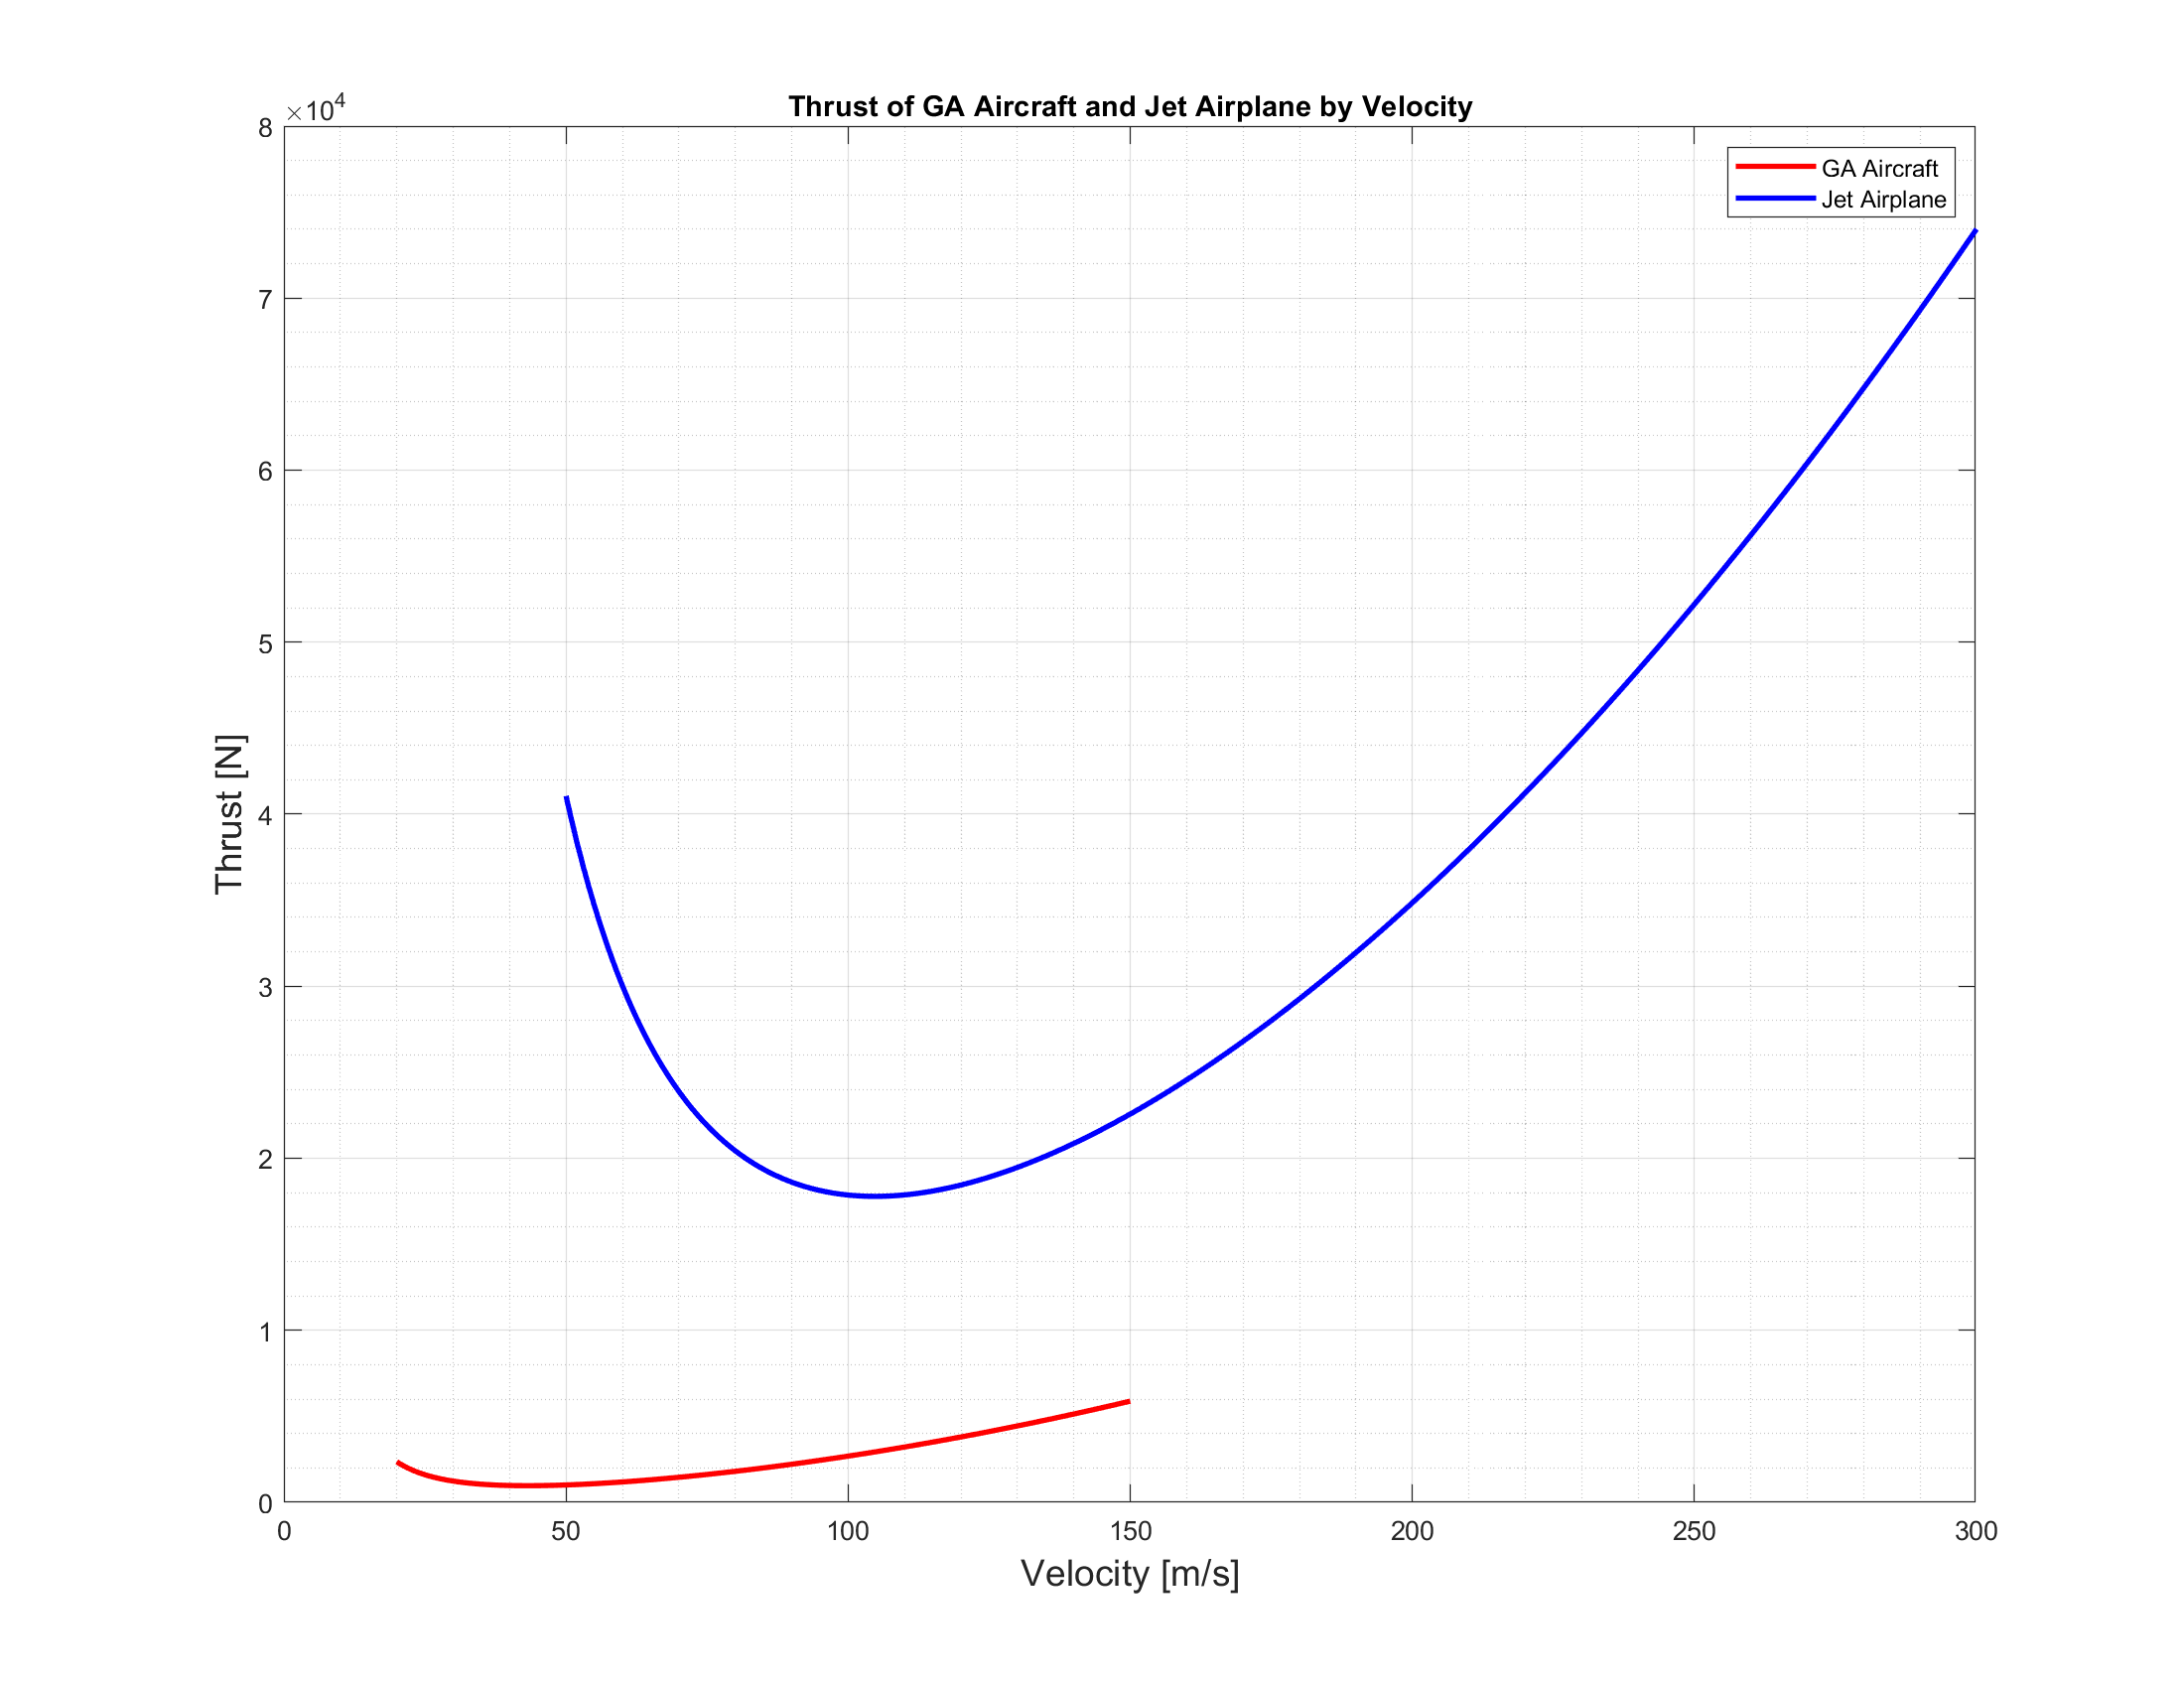

% Adjusting fontsize and linewidth
fontsize = 14;
linewidth = 2;

% GA aircraft & jet airplane Thrust
figure(1)
plot(vel_prop, propThrust, '-r', 'LineWidth', linewidth)
title('Thrust of GA Aircraft and Jet Airplane by Velocity')
xlabel('Velocity [m/s]', 'FontSize',fontsize)
ylabel('Thrust [N]', 'FontSize',fontsize)
grid on 
grid minor
box on
hold on
plot(vel_jet, jetThrust, '-b','LineWidth',linewidth)
hold off
legend('GA Aircraft', 'Jet Airplane')
% Positioning 
set(gcf,'PaperPositionMode','auto','Position',[0 0 1100 850])

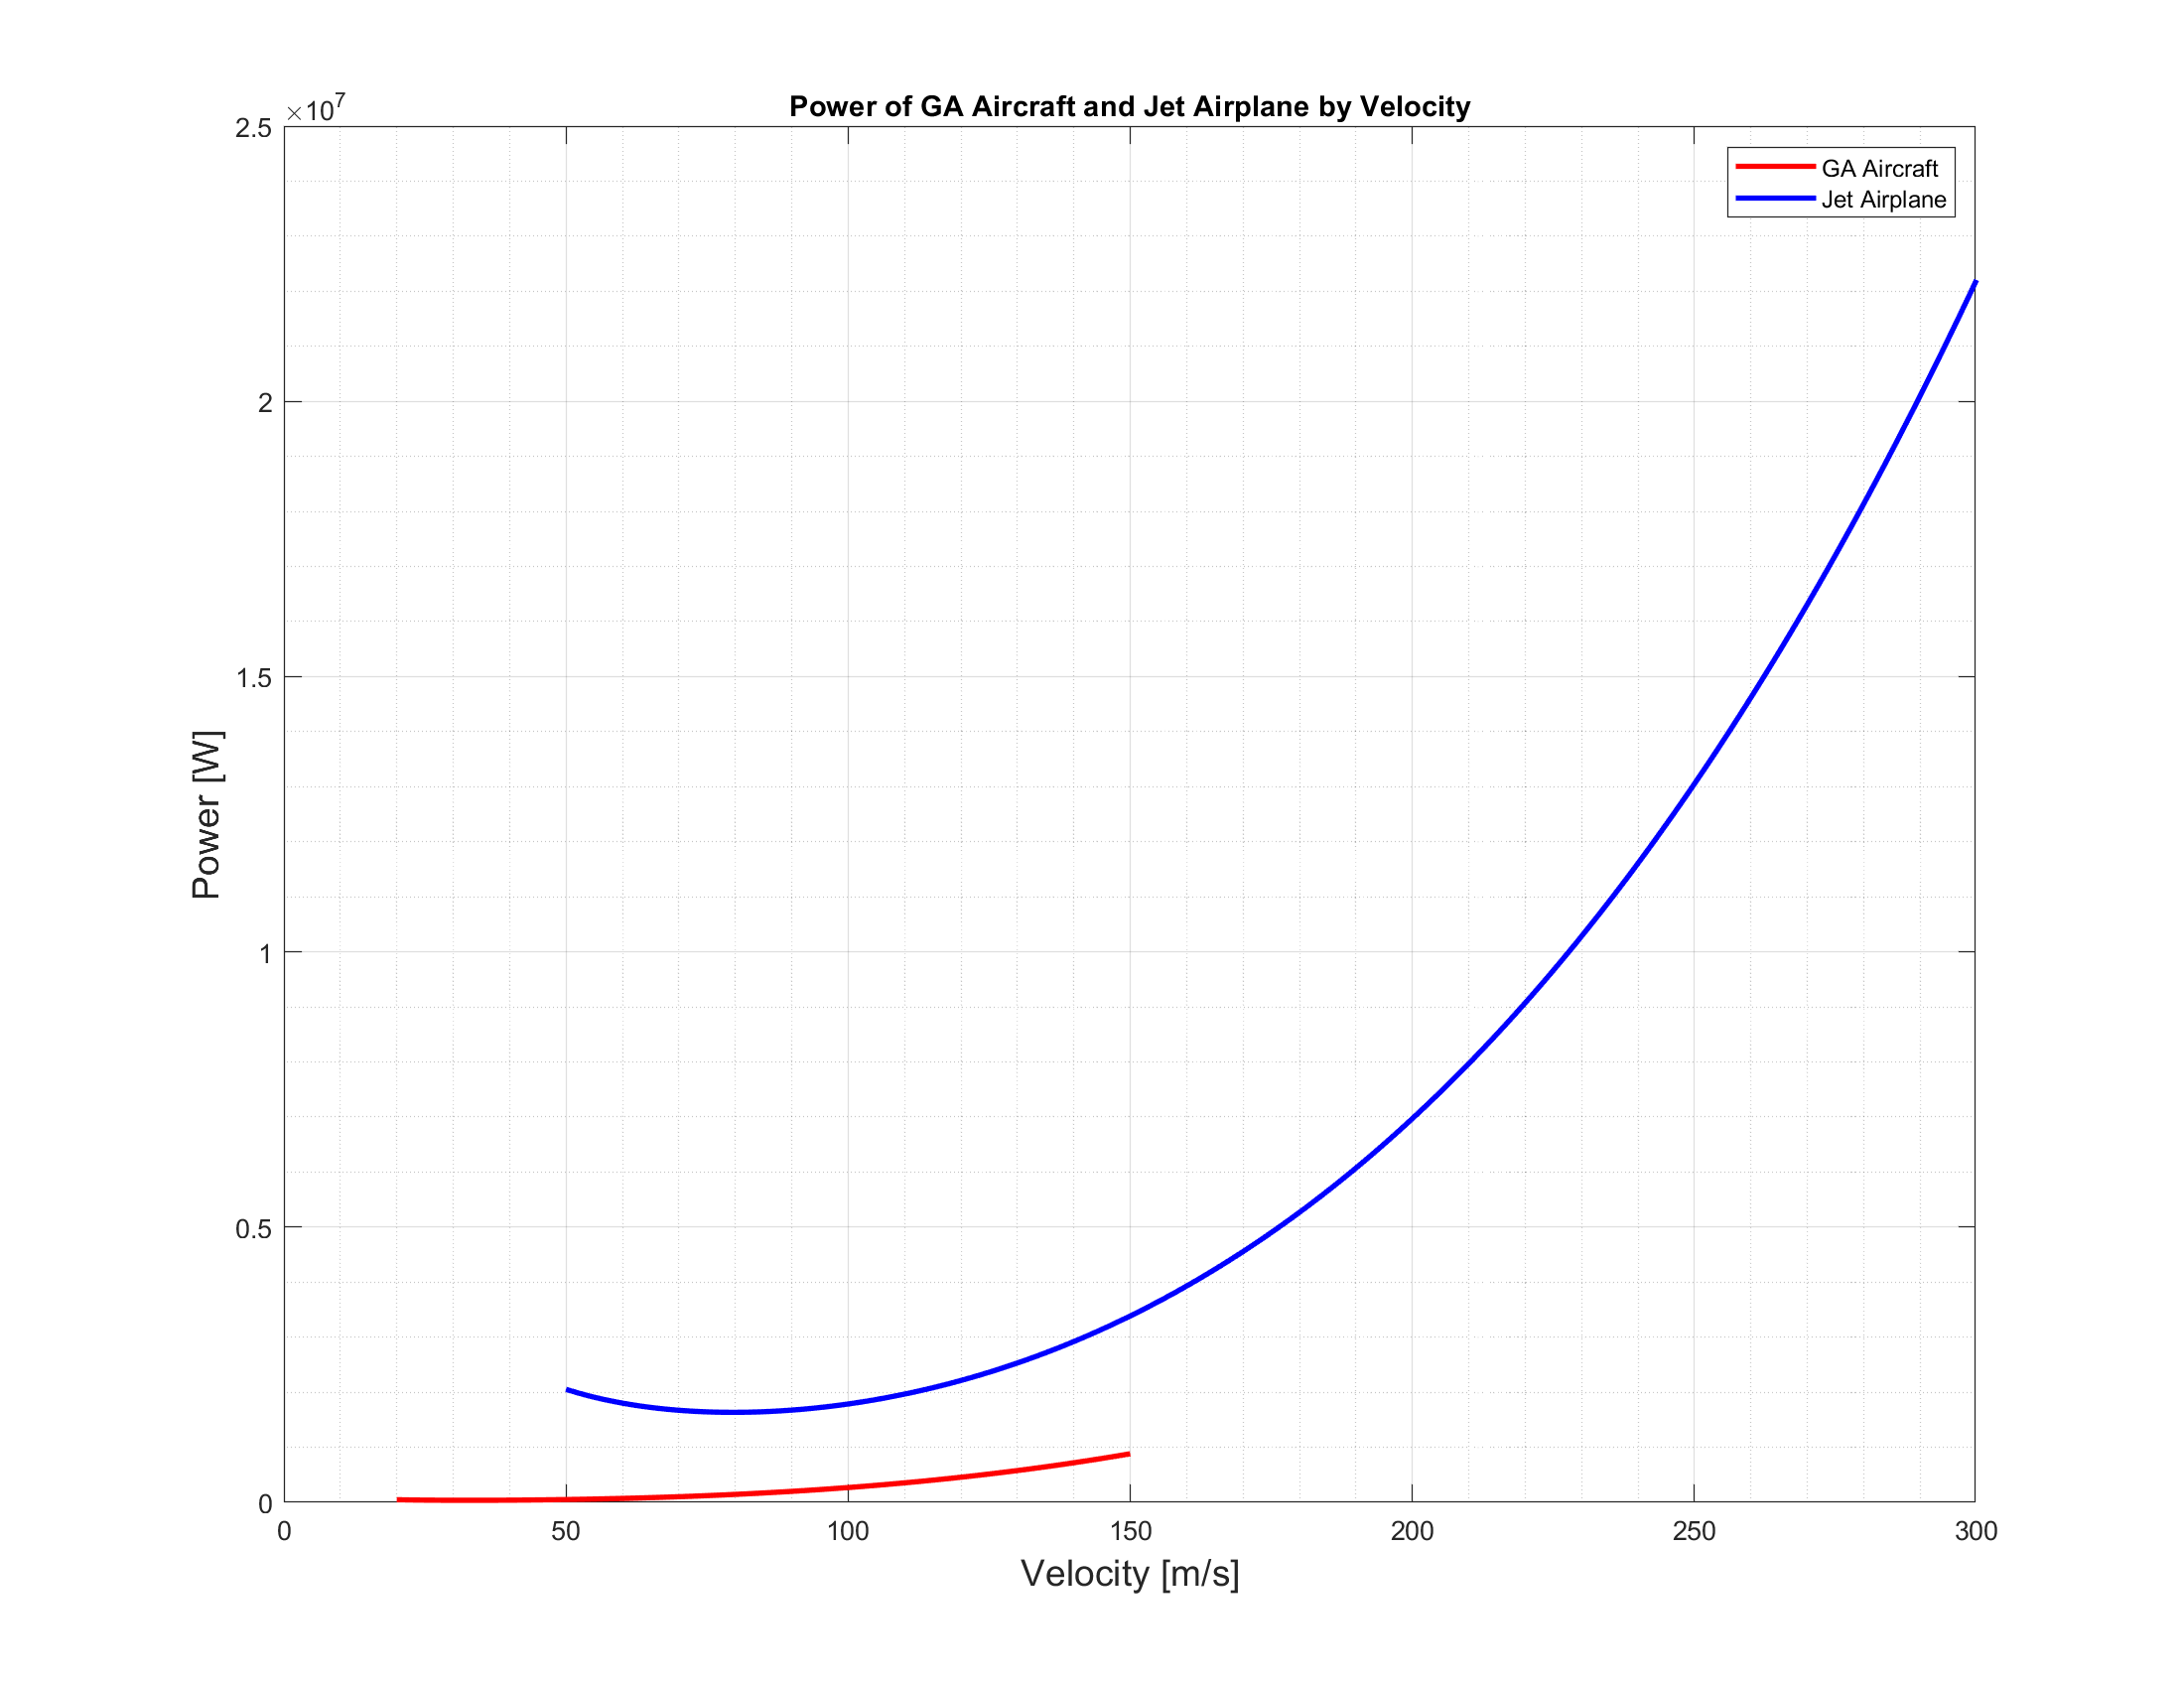


% GA aircraft & jet airplane power
figure(2)
plot(vel_prop, propPower, '-r', 'LineWidth', linewidth)
title('Power of GA Aircraft and Jet Airplane by Velocity')
xlabel('Velocity [m/s]', 'FontSize',fontsize)
ylabel('Power [W]', 'FontSize',fontsize)
grid on 
grid minor
box on
hold on
plot(vel_jet, jetPower, '-b','LineWidth',linewidth)
hold off
legend('GA Aircraft', 'Jet Airplane')

% Positioning 
set(gcf,'PaperPositionMode','auto','Position',[0 0 1100 850])